# The use of $\mathcal{K}$-FCA for the analysis of *C. elegans'* sensorium - Visualization

This live script loads the result tables generated in the previous analysis (result_table_conc*.mat) and produces all the figures used in the paper.

The figures include:

- Mean ± STD curves for all concentrations, in both min-plus and max-plus semirings

- Histograms of minimal-variance $\varphi$ values.

- Cumulative histograms of minimal-variance $\varphi$ values.

Please cite the corresponding paper when using this script:

DOI: XXXXXXXXX

Author: Emma Reyner-Fuentes; Carmen Peláez-Moreno, Francisco J. Valverde-Albacete

Date: 29/07/2025

## Min-Plus semiring - Setup

clearvars
close all

% Add path to the data
path(matlabpath, '/yourPath/data/output/result_tables/');

maxplus = 0;

## Mean ± STD Curves for All Concentrations

figure;
hold on;

% Base colors for each concentration (blue, yellow, green)
base_colors = { [0 0.4470 0.7410], ...
                [0.9290 0.6940 0.1250], ...
                [0.4660 0.6740 0.1880] };

concentrations = [4, 5, 6];
legends = {};

for i = 1:length(concentrations)
    % --- Load result table for this concentration ---
    variable_name = 'result_table';
    loaded_data = load(sprintf('result_table_conc%d.mat', concentrations(i)), variable_name);
    result_table = loaded_data.(variable_name);

    % --- Extract fields from the table ---
    K1_Phis_uniform = result_table.K1_Phis_uniform;
    mean_nc         = result_table.mean_nc;
    std_nc          = result_table.std_nc;
    upper_bound     = result_table.upper_bound;
    lower_bound     = result_table.lower_bound;

    % Use selected minima (as stored in the result_table)
    selected_phis   = result_table.selected_phis;
    selected_indices = result_table.selected_indices;

    % --- Plot shaded area for mean ± std ---
    fill_x = [K1_Phis_uniform(:)', fliplr(K1_Phis_uniform(:)')];
    fill_y = [upper_bound(:)', fliplr(lower_bound(:)')];
    fill(fill_x, fill_y, base_colors{i}, ...
        'EdgeColor', base_colors{i}, 'FaceAlpha', 0.1);

    % --- Plot mean curve ---
    plot(K1_Phis_uniform, mean_nc, 'Color', base_colors{i}, 'LineWidth', 2);

    % --- Plot the selected minima points as filled scatter points ---
    dark_factor = 0.5; % Darker color for the points
    std_color = base_colors{i} * dark_factor;
    x_points = K1_Phis_uniform(selected_indices);
    y_points = mean_nc(selected_indices);

    scatter(x_points, y_points, 10, 'filled', ...
        'MarkerEdgeColor', std_color, 'MarkerFaceColor', std_color);

    % --- Add legend entries ---
    legends{end+1} = sprintf('STD interval - $10^{-%d}$', concentrations(i));
    legends{end+1} = sprintf('Mean - $10^{-%d}$', concentrations(i));
    legends{end+1} = sprintf('Minima - $10^{-%d}$', concentrations(i));
end

% --- Configure plot labels and legend ---
title('Number of Concepts: Mean $\pm$ STD and Local Minima', ...
    'FontSize', 14, 'FontWeight', 'bold', 'Interpreter', 'latex');
xlabel('$\varphi$', 'Interpreter', 'latex');
ylabel('Number of concepts');
legend(legends, 'Interpreter', 'latex', 'Location', 'best');

% --- Print values of φ and STD for each concentration ---
for i = 1:length(concentrations)
    variable_name = 'result_table';
    loaded_data = load(sprintf('result_table_conc%d.mat', concentrations(i)), variable_name);
    result_table = loaded_data.(variable_name);

    fprintf('Concentration %d:\n', concentrations(i));
    for j = 1:length(result_table.selected_phis)
        fprintf('  Phi: %.3f, STD: %.4f\n', ...
            result_table.selected_phis(j), ...
            result_table.selected_std(j));
    end
end

Concentration 4:


  Phi: 0.798, STD: 0.0000
  Phi: 0.148, STD: 0.4472
  Phi: 0.228, STD: 0.4472
  Phi: 0.382, STD: 0.4472
  Phi: 0.396, STD: 0.4472
  Phi: 0.400, STD: 0.4472
  Phi: 0.526, STD: 0.4472
  Phi: 0.753, STD: 0.4472
  Phi: 0.926, STD: 0.4472
  Phi: 1.095, STD: 0.4472
  Phi: 0.194, STD: 0.5477
  Phi: 0.865, STD: 0.5477
  Phi: 0.743, STD: 0.5477
  Phi: 0.722, STD: 0.7071
  Phi: 0.191, STD: 0.8367
  Phi: 0.593, STD: 0.8367
  Phi: 0.775, STD: 0.8367
  Phi: 0.904, STD: 0.8367
  Phi: 0.967, STD: 0.8367
  Phi: 0.973, STD: 0.8367
  Phi: 1.004, STD: 0.8367
  Phi: 0.404, STD: 0.8944
  Phi: 0.495, STD: 0.8944
  Phi: 0.575, STD: 0.8944
  Phi: 0.707, STD: 0.8944
  Phi: 0.888, STD: 0.8944
  Phi: 0.338, STD: 1.0000
  Phi: 0.589, STD: 1.0000
  Phi: 0.361, STD: 1.0954
  Phi: 0.136, STD: 1.0954
  Phi: 0.478, STD: 1.0954
  Phi: 0.618, STD: 1.1402
  Phi: 0.670, STD: 1.1402
  Phi: 0.203, STD: 1.1402
  Phi: 0.342, STD: 1.1402
  Phi: 0.424, STD: 1.1402
  Phi: 0.408, STD: 1.2247
  Phi: 0.499, STD: 1.3038
  Phi: 0.662

Concentration 5:


  Phi: 0.165, STD: 0.0000
  Phi: 0.561, STD: 0.4472
  Phi: 0.587, STD: 0.4472
  Phi: 0.455, STD: 0.4472
  Phi: 0.238, STD: 0.5477
  Phi: 0.794, STD: 0.5477
  Phi: 0.034, STD: 0.7071
  Phi: 0.473, STD: 0.7071
  Phi: 0.779, STD: 0.7071
  Phi: 0.041, STD: 0.8367
  Phi: 0.289, STD: 0.8367
  Phi: 0.360, STD: 0.8367
  Phi: 0.397, STD: 0.8367
  Phi: 0.408, STD: 0.8367
  Phi: 0.492, STD: 0.8367
  Phi: 0.140, STD: 0.8944
  Phi: 0.390, STD: 0.8944
  Phi: 0.056, STD: 1.0954
  Phi: 0.421, STD: 1.0954
  Phi: 0.047, STD: 1.1402
  Phi: 0.304, STD: 1.1402
  Phi: 0.269, STD: 1.1402
  Phi: 0.309, STD: 1.3038
  Phi: 0.317, STD: 1.3038
  Phi: 0.384, STD: 1.3038
  Phi: 0.541, STD: 1.3038
  Phi: 0.073, STD: 1.3038
  Phi: 0.211, STD: 1.3416
  Phi: 0.506, STD: 1.3416
  Phi: 0.052, STD: 1.4832
  Phi: 0.530, STD: 1.4832
  Phi: 0.250, STD: 1.5166
  Phi: 0.366, STD: 1.5166
  Phi: 0.807, STD: 1.5166
  Phi: 0.917, STD: 1.6432
  Phi: 0.022, STD: 1.6733
  Phi: 0.255, STD: 1.6733
  Phi: 0.515, STD: 1.6733
  Phi: 0.062

Concentration 6:


  Phi: 0.099, STD: 0.0000
  Phi: 0.318, STD: 0.0000
  Phi: 0.498, STD: 0.0000
  Phi: 0.121, STD: 0.4472
  Phi: 0.203, STD: 0.4472
  Phi: 0.208, STD: 0.4472
  Phi: 0.249, STD: 0.4472
  Phi: 0.253, STD: 0.4472
  Phi: 0.268, STD: 0.4472
  Phi: 0.324, STD: 0.4472
  Phi: 0.112, STD: 0.5477
  Phi: 0.482, STD: 0.5477
  Phi: 0.180, STD: 0.5477
  Phi: 0.184, STD: 0.5477
  Phi: 0.240, STD: 0.5477
  Phi: 0.454, STD: 0.5477
  Phi: 0.057, STD: 0.7071
  Phi: 0.217, STD: 0.7071
  Phi: 0.338, STD: 0.7071
  Phi: 0.025, STD: 0.8367
  Phi: 0.029, STD: 0.8367
  Phi: 0.160, STD: 0.8367
  Phi: 0.163, STD: 0.8367
  Phi: 0.236, STD: 0.8367
  Phi: 0.388, STD: 0.8367
  Phi: 0.378, STD: 0.8944
  Phi: 0.390, STD: 0.8944
  Phi: 0.151, STD: 1.0000
  Phi: 0.168, STD: 1.0000
  Phi: 0.176, STD: 1.0000
  Phi: 0.027, STD: 1.0954
  Phi: 0.037, STD: 1.1402
  Phi: 0.046, STD: 1.1402
  Phi: 0.050, STD: 1.1402
  Phi: 0.075, STD: 1.1402
  Phi: 0.079, STD: 1.2247
  Phi: 0.154, STD: 1.2247
  Phi: 0.019, STD: 1.3038
  Phi: 0.281

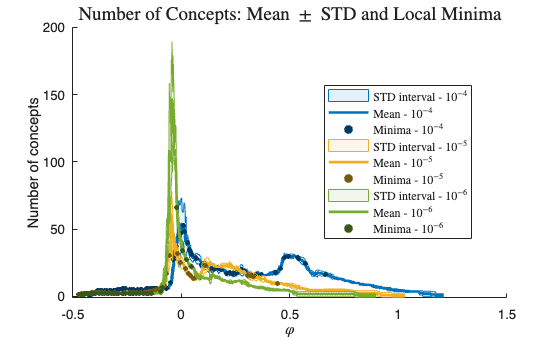


hold off;

## Histogram of Minimal-Variance $\varphi$ Values

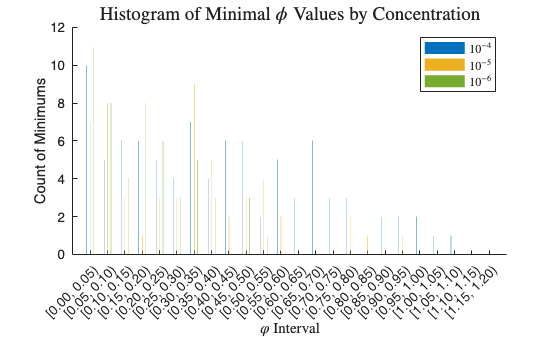

figure;
hold on;

% Base colors and concentrations
base_colors = { [0 0.4470 0.7410], ...
                [0.9290 0.6940 0.1250], ...
                [0.4660 0.6740 0.1880] };
concentrations = [4, 5, 6];
legends = {};

% Histogram configuration
bin_size = 0.05;
bin_edges = 0:bin_size:1.2;
bin_centers = bin_edges(1:end-1) + diff(bin_edges) / 2;
bar_width = 0.02;

num_concentrations = length(concentrations);
all_histogram_counts = zeros(num_concentrations, length(bin_centers));

for i = 1:num_concentrations
    % --- Load result table ---
    loaded_data = load(sprintf('result_table_conc%d.mat', concentrations(i)), 'result_table');
    result_table = loaded_data.result_table;

    % --- Use the new field selected_phis ---
    selected_phis = result_table.selected_phis;

    % --- Filter φ values based on sign (positive for Rmin, negative for max-plus) ---
    if maxplus == 0
        filtered_phis = selected_phis(selected_phis > 0);
    else
        filtered_phis = selected_phis(selected_phis < 0);
    end

    % --- Compute histogram counts ---
    histogram_counts = histcounts(filtered_phis, bin_edges);
    all_histogram_counts(i, :) = histogram_counts;

    % --- Offset for grouped bars ---
    if i == 1
        offset = -0.01;
    elseif i == 2
        offset = 0;
    elseif i == 3
        offset = 0.01;
    end
    adjusted_bin_centers = bin_centers + offset;

    % --- Plot bars ---
    bar(adjusted_bin_centers, histogram_counts, bar_width, ...
        'FaceColor', base_colors{i}, 'EdgeColor', 'none', ...
        'DisplayName', sprintf('$10^{-%d}$', concentrations(i)));
end

% Dynamic x-axis labels
num_decimals = max(0, -floor(log10(bin_size)));
format_str = sprintf('[%%.%df, %%.%df)', num_decimals, num_decimals);
xticks(bin_centers);
xticklabels(arrayfun(@(x) sprintf(format_str, bin_edges(x), bin_edges(x+1)), ...
    1:length(bin_centers), 'UniformOutput', false));

% Plot labels and legend
title('Histogram of Minimal $\phi$ Values by Concentration', ...
    'FontSize', 14, 'FontWeight', 'bold', 'Interpreter','latex');
xlabel('$\varphi$ Interval', 'Interpreter','latex');
ylabel('Count of Minimums');
legend('show', 'Interpreter', 'latex');

hold off;

## Cumulative Histogram of Minimal-Variance $\varphi$ Values

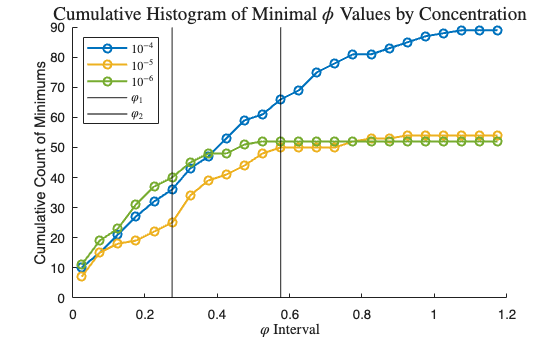

figure;
hold on;

% Base colors and concentrations
base_colors = { [0 0.4470 0.7410], ...
                [0.9290 0.6940 0.1250], ...
                [0.4660 0.6740 0.1880] };
concentrations = [4, 5, 6];

% Histogram configuration
bin_size = 0.05;
bin_edges = 0:bin_size:1.2;
bin_centers = bin_edges(1:end-1) + diff(bin_edges) / 2;

num_concentrations = length(concentrations);

for i = 1:num_concentrations
    % --- Load result table ---
    loaded_data = load(sprintf('result_table_conc%d.mat', concentrations(i)), 'result_table');
    result_table = loaded_data.result_table;

    % --- Use the new field selected_phis ---
    selected_phis = result_table.selected_phis;

    % --- Filter φ values ---
    if maxplus == 0
        filtered_phis = selected_phis(selected_phis > 0);
    else
        filtered_phis = selected_phis(selected_phis < 0);
    end

    % --- Compute cumulative histogram ---
    histogram_counts = histcounts(filtered_phis, bin_edges);
    cumulative_counts = cumsum(histogram_counts);

    % --- Plot cumulative histogram ---
    plot(bin_centers, cumulative_counts, '-o', 'Color', base_colors{i}, ...
        'LineWidth', 1.5, 'DisplayName', sprintf('$10^{-%d}$', concentrations(i)));
end

% Vertical reference lines for φ
xline(0.275, 'k', 'LineWidth', 1, 'DisplayName', '$\varphi_1$');
xline(0.575, 'k', 'LineWidth', 1, 'DisplayName', '$\varphi_2$');

% Labels and legend
title('Cumulative Histogram of Minimal $\phi$ Values by Concentration', ...
    'FontSize', 14, 'FontWeight', 'bold', 'Interpreter','latex');
xlabel('$\varphi$ Interval', 'Interpreter','latex');
ylabel('Cumulative Count of Minimums');
legend('show', 'Interpreter', 'latex', 'Location', 'northwest');

hold off;

## Max-Plus semiring - Setup

clearvars
close all

% Add path to the data
path(matlabpath, '/Users/emmareynerfuentes/Desktop/PHD/paper_methods/data/output/result_tables/');

maxplus = 1;

## Mean ± STD Curves for All Concentrations (Max-Plus)

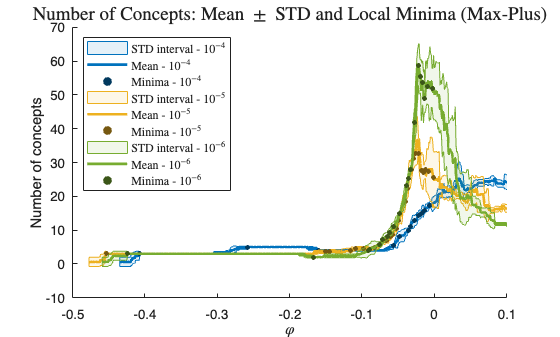

% Prepare figure
figure;
hold on;

% Base colors for each concentration (blue, yellow, green)
base_colors = { [0 0.4470 0.7410], ...
                [0.9290 0.6940 0.1250], ...
                [0.4660 0.6740 0.1880] };

concentrations = [4, 5, 6];
legends = {};

for i = 1:length(concentrations)

    % --- Choose correct filename ---
    if maxplus == 1
        filename = sprintf('result_table_conc%d_maxplus.mat', concentrations(i));
    else
        filename = sprintf('result_table_conc%d.mat', concentrations(i));
    end
    variable_name = 'result_table';

    % --- Load result table ---
    loaded_data = load(filename, variable_name);
    result_table = loaded_data.(variable_name);

    % --- Extract fields ---
    K1_Phis_uniform  = result_table.K1_Phis_uniform;
    mean_nc          = result_table.mean_nc;
    upper_bound      = result_table.upper_bound;
    lower_bound      = result_table.lower_bound;
    selected_phis    = result_table.selected_phis;
    selected_indices = result_table.selected_indices;

    % Valores medios en los mínimos seleccionados
    selected_mean_values = mean_nc(selected_indices);

    % --- Área sombreada para mean ± std ---
    fill_x = [K1_Phis_uniform(:)', fliplr(K1_Phis_uniform(:)')];
    fill_y = [upper_bound(:)', fliplr(lower_bound(:)')];
    fill(fill_x, fill_y, base_colors{i}, ...
        'EdgeColor', base_colors{i}, 'FaceAlpha', 0.1);

    % --- Curva de la media ---
    plot(K1_Phis_uniform, mean_nc, 'Color', base_colors{i}, 'LineWidth', 2);

    % --- Puntos de los mínimos locales ---
    dark_factor = 0.5;
    std_color = base_colors{i} * dark_factor;
    scatter(selected_phis, selected_mean_values, 10, 'filled', ...
        'MarkerEdgeColor', std_color, 'MarkerFaceColor', std_color);

    % --- Leyenda ---
    legends{end+1} = sprintf('STD interval - $10^{-%d}$', concentrations(i));
    legends{end+1} = sprintf('Mean - $10^{-%d}$', concentrations(i));
    legends{end+1} = sprintf('Minima - $10^{-%d}$', concentrations(i));
end

title('Number of Concepts: Mean $\pm$ STD and Local Minima (Max-Plus)', ...
    'FontSize', 14, 'FontWeight', 'bold', 'Interpreter', 'latex');
xlabel('$\varphi$', 'Interpreter', 'latex');
ylabel('Number of concepts');
legend(legends, 'Interpreter', 'latex', 'Location', 'northwest');
xlim([-0.5 0.1]); % Zona negativa para max-plus
hold off;

## Histogram of Minimal-Variance $\varphi$ Values (Max-Plus)

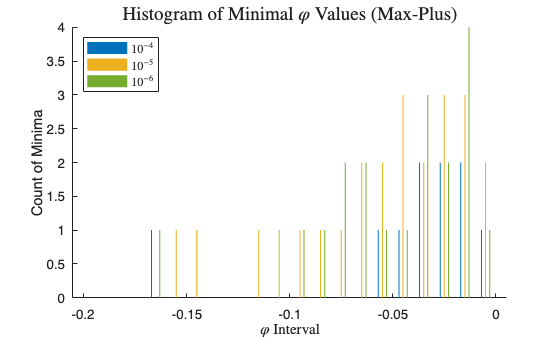

figure;
hold on;

base_colors = { [0 0.4470 0.7410], ...
                [0.9290 0.6940 0.1250], ...
                [0.4660 0.6740 0.1880] };

concentrations = [4, 5, 6];

bin_size = 0.01;
bin_edges = -0.2:bin_size:0; % Rango negativo
bin_centers = bin_edges(1:end-1) + diff(bin_edges)/2;
bar_width = 0.05;

for i = 1:length(concentrations)

    % --- Load table ---
    if maxplus == 1
        filename = sprintf('result_table_conc%d_maxplus.mat', concentrations(i));
    else
        filename = sprintf('result_table_conc%d.mat', concentrations(i));
    end
    variable_name = 'result_table';
    loaded_data = load(filename, variable_name);
    result_table = loaded_data.(variable_name);

    % --- Extraer y filtrar φ negativas ---
    filtered_phis = result_table.selected_phis(result_table.selected_phis < 0);

    % --- Histograma ---
    histogram_counts = histcounts(filtered_phis, bin_edges);

    % Offset para barras
    offsets = [-0.002, 0, 0.002];
    adjusted_bin_centers = bin_centers + offsets(i);

    bar(adjusted_bin_centers, histogram_counts, bar_width, ...
        'FaceColor', base_colors{i}, 'EdgeColor', 'none', ...
        'DisplayName', sprintf('$10^{-%d}$', concentrations(i)));
end

title('Histogram of Minimal $\varphi$ Values (Max-Plus)', ...
    'FontSize', 14, 'FontWeight', 'bold', 'Interpreter', 'latex');
xlabel('$\varphi$ Interval', 'Interpreter', 'latex');
ylabel('Count of Minima');
legend('show', 'Interpreter', 'latex', 'Location', 'northwest');
hold off;

## Cumulative Histogram of Minimal-Variance $\varphi$ Values (Max-Plus)

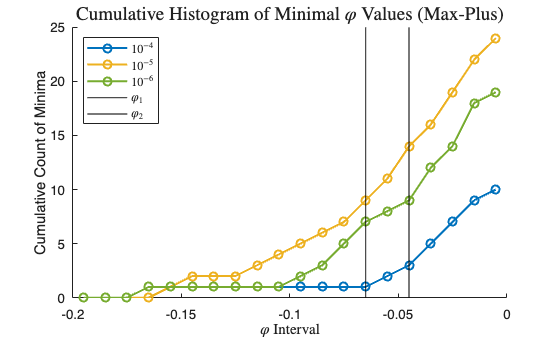

figure;
hold on;

bin_size = 0.01;
bin_edges = -0.2:bin_size:0;
bin_centers = bin_edges(1:end-1) + diff(bin_edges)/2;

for i = 1:length(concentrations)

    % --- Load table ---
    if maxplus == 1
        filename = sprintf('result_table_conc%d_maxplus.mat', concentrations(i));
    else
        filename = sprintf('result_table_conc%d.mat', concentrations(i));
    end
    variable_name = 'result_table';
    loaded_data = load(filename, variable_name);
    result_table = loaded_data.(variable_name);

    % --- Extraer φ negativas ---
    filtered_phis = result_table.selected_phis(result_table.selected_phis < 0);

    % --- Histograma acumulativo ---
    histogram_counts = histcounts(filtered_phis, bin_edges);
    cumulative_counts = cumsum(histogram_counts);

    plot(bin_centers, cumulative_counts, '-o', ...
        'Color', base_colors{i}, 'LineWidth', 1.5, ...
        'DisplayName', sprintf('$10^{-%d}$', concentrations(i)));
end

xline(-0.065, 'k', 'LineWidth', 1, 'DisplayName', '$\varphi_1$');
xline(-0.045, 'k', 'LineWidth', 1, 'DisplayName', '$\varphi_2$');

title('Cumulative Histogram of Minimal $\varphi$ Values (Max-Plus)', ...
    'FontSize', 14, 'FontWeight', 'bold', 'Interpreter', 'latex');
xlabel('$\varphi$ Interval', 'Interpreter', 'latex');
ylabel('Cumulative Count of Minima');
legend('show', 'Interpreter', 'latex', 'Location', 'northwest');
hold off;